clear; clc; clearvars;

Entrada de dados:

% x=input('Entre com os valores(independentes) do vetor X');
x= [0 1 2.5 3 4.5 5 6];
% y=input('Entre com os valores(dependentes) do vetor Y');
y =[2 5.4375 7.3516 7.5625 8.4453 9.1875 12];

Processamento do problema:

n=length(x); 
if length(y)~=n, error('x e y devem ter obrigatoriamente o mesmo tamanho!'); 
end
% xf=input('Digite o valor de x onde se quer encontrar o valor de f(x): ');
xf = 3.5;

Cria uma matriz quadrada L de tamanho n preenchida com zeros: 

L=zeros(n); %diferenças divididas 

Preenchendo a primeira coluna da matriz L como espelho de y transposto

for k=1:n %vetor varrendo o tamanho da matriz de vetores x independentes
   L(k,1)=y(k); 
end

for k=2:n %calcula a partir da segunda ordem (coluna) da matriz L %quantidade de linhas:tamanho de n
  for m=1:n-k                     
       L(m,k)=(L(m,k-1)-L(m+1,k-1))/(x(m)-x(m+(k-1)));
  end
end

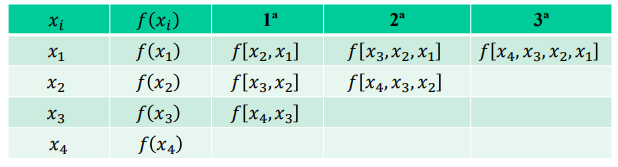

Tabela com os resultados:

tabela= [x' L]

tabela =          0    2.0000    3.4375   -0.8646    0.1458    0.0000   -0.0000         0
    1.0000    5.4375    1.2761   -0.4271    0.1459   -0.0000         0         0
    2.5000    7.3516    0.4218    0.0834    0.1458         0         0         0
    3.0000    7.5625    0.5885    0.4479         0         0         0         0
    4.5000    8.4453    1.4844         0         0         0         0         0
    5.0000    9.1875         0         0         0         0         0         0
    6.0000   12.0000         0         0         0         0         0         0


Encontrando o valor desejado para f(x) com o x requerido:

s=1;
t=0;
sol=y(1);
for k=2:n
   s=s*(xf-x(k-1));
   t=s*L(1,k);
   sol=sol+t;
end
disp(['O valor de x: ',num2str(xf),' requerido para f(x) é: ',num2str(sol)])

O valor de x: 3.5 requerido para f(x) é: 7.7422
